# Study on Delay Embedding

## Initialization

clear
close all
clc

addpath(genpath('Data'));
addpath(genpath('Figures'));
addpath(genpath('Modular Models'));
addpath(genpath('Scripts'));

motor_params;

## Data Loading and Preparation

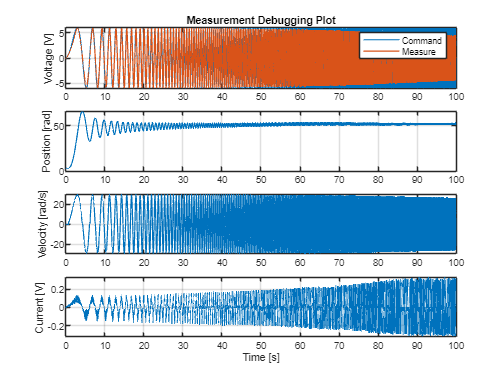

load('D:\Data\_PROGETTI\PRJ_SMART_SERVO\MATLAB\Data\Motor_Voltage_Chirp_Experiment.mat');
dataset = exp_to_std(data); clear data;

dataset.velocity = sgolayfilt(gradient(dataset.position)/1e-3, 1, 21);
dataset.acceleration = sgolayfilt(gradient(dataset.velocity)/1e-3, 1, 21);

dataset.current_f1 = sgolayfilt(dataset.current, 3, 11);
dataset.current_f2 = sgolayfilt(dataset.current_f1, 3, 11);
dataset.current_f3 = sgolayfilt(dataset.current_f2, 3, 11);


fig = figure();

subplot(4,1,1), plot(dataset.time, dataset.command*6, dataset.time, dataset.voltage, 'LineWidth', 1)
lgd = legend('Command', 'Measure');
ylabel('Voltage [V]')
grid on

title('Measurement Debugging Plot')

subplot(4,1,2), plot(dataset.time, dataset.position, 'LineWidth', 1)
ylabel('Position [rad]')
grid on

subplot(4,1,3), plot(dataset.time, dataset.velocity, 'LineWidth', 1)
ylabel('Velocity [rad/s]')
grid on

subplot(4,1,4), plot(dataset.time, dataset.current, 'LineWidth', 1)
ylabel('Current [V]'), xlabel('Time [s]')
grid on

## Hankel Matrix Construction

tic

y = downsample([dataset.position, dataset.velocity, dataset.current, dataset.voltage], 2);

xlen = 10000;
ylen = 5000;
n_states = 4;
H = zeros(n_states*ylen, xlen);

for i = 1:ylen
    H(1 + n_states*(i-1):n_states*i, 1:xlen) = y(i:xlen+i-1, :).'; 
end

toc

Elapsed time is 2.569968 seconds.


## SVD

tic

[u, s, v] = svd(H, 'econ');

toc

Elapsed time is 489.975326 seconds.


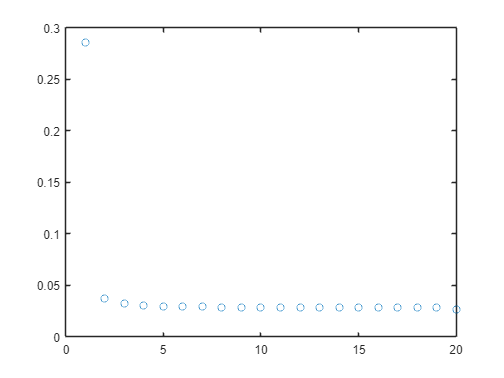

figure()
plot(diag(s)/(sum(diag(s))), ' o')
xlim([0,20])

diag(s)

ans = 1.0e+05 *

    3.3748
    0.4322
    0.3765
    0.3524
    0.3487
    0.3430
    0.3404
    0.3392
    0.3379
    0.3369


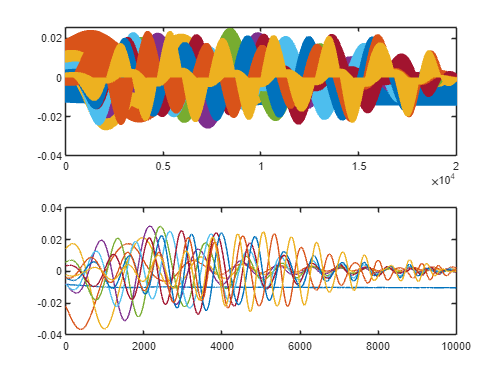

figure()
subplot(2,1,1), plot(u(:, 1:10))
subplot(2,1,2), plot(v(:, 1:10))